## Problem 1

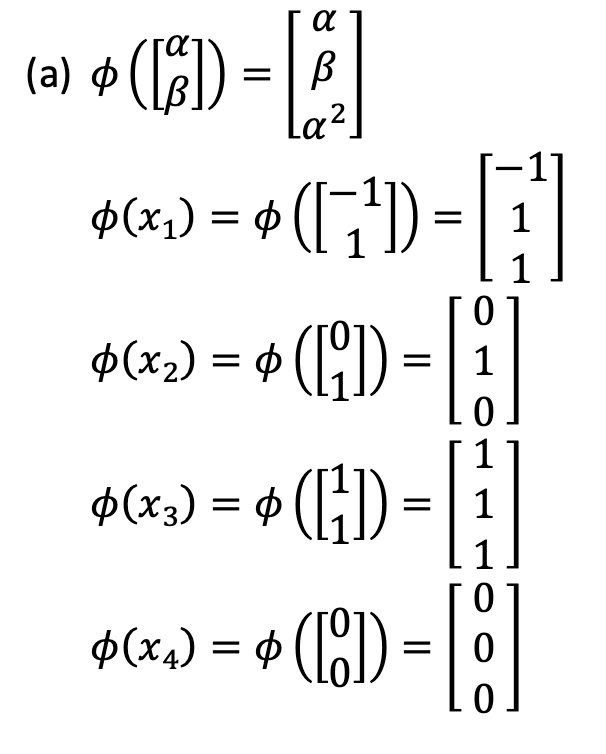

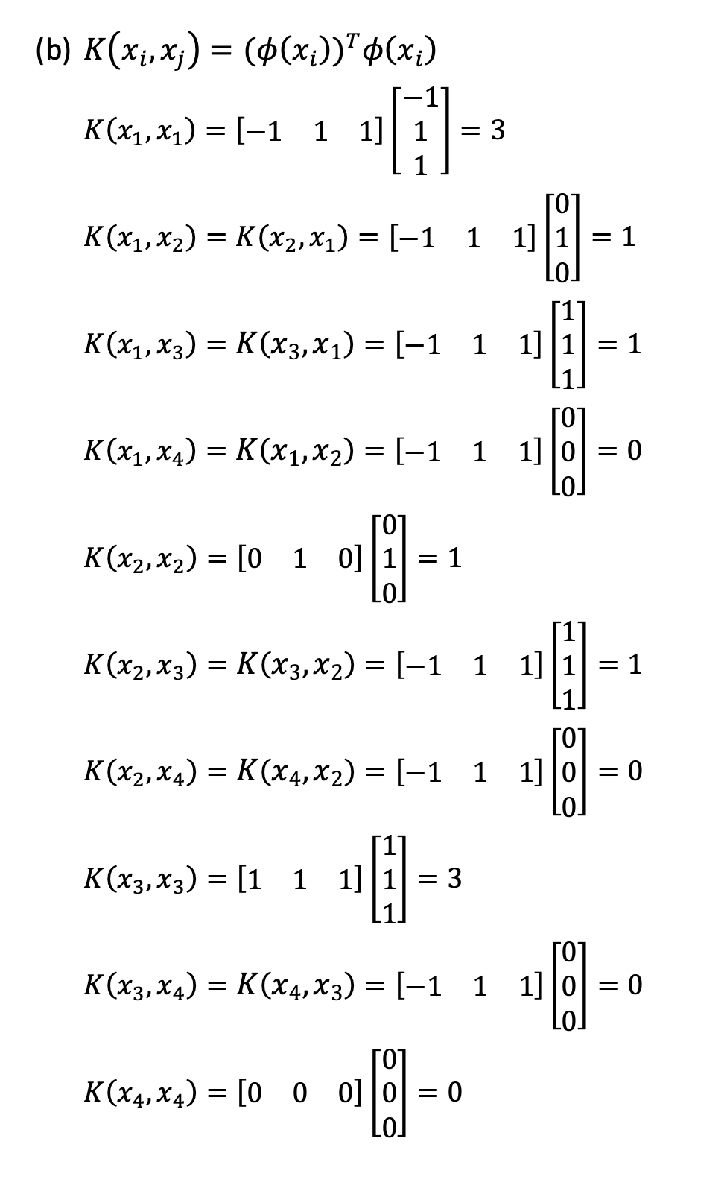

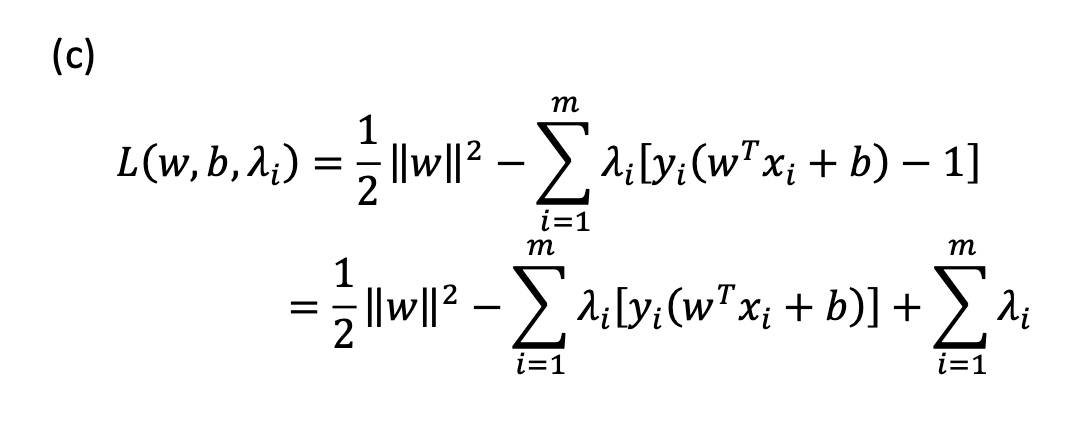

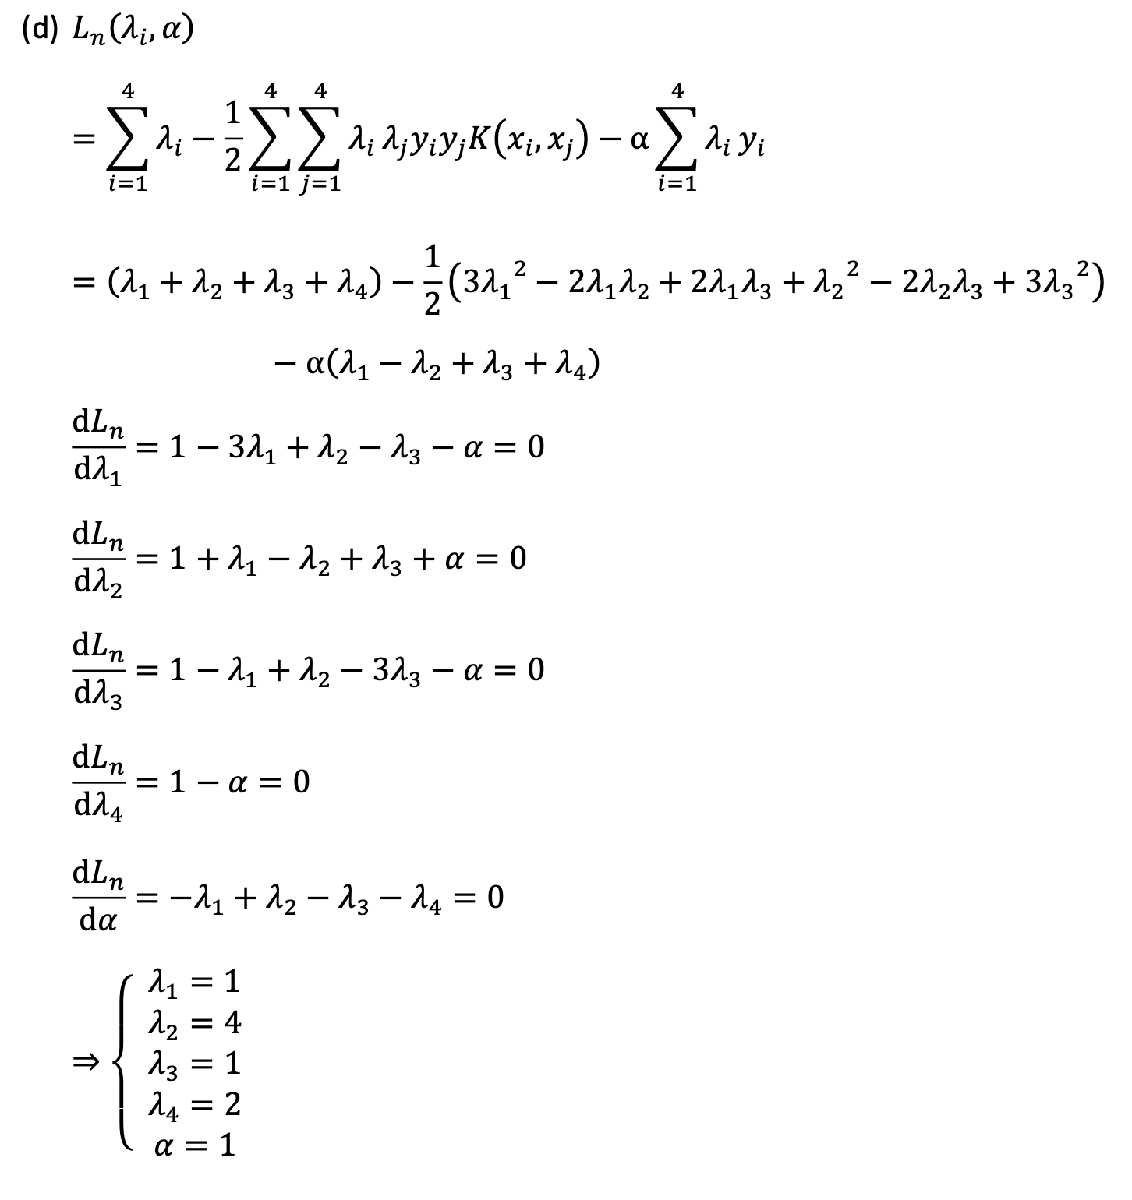

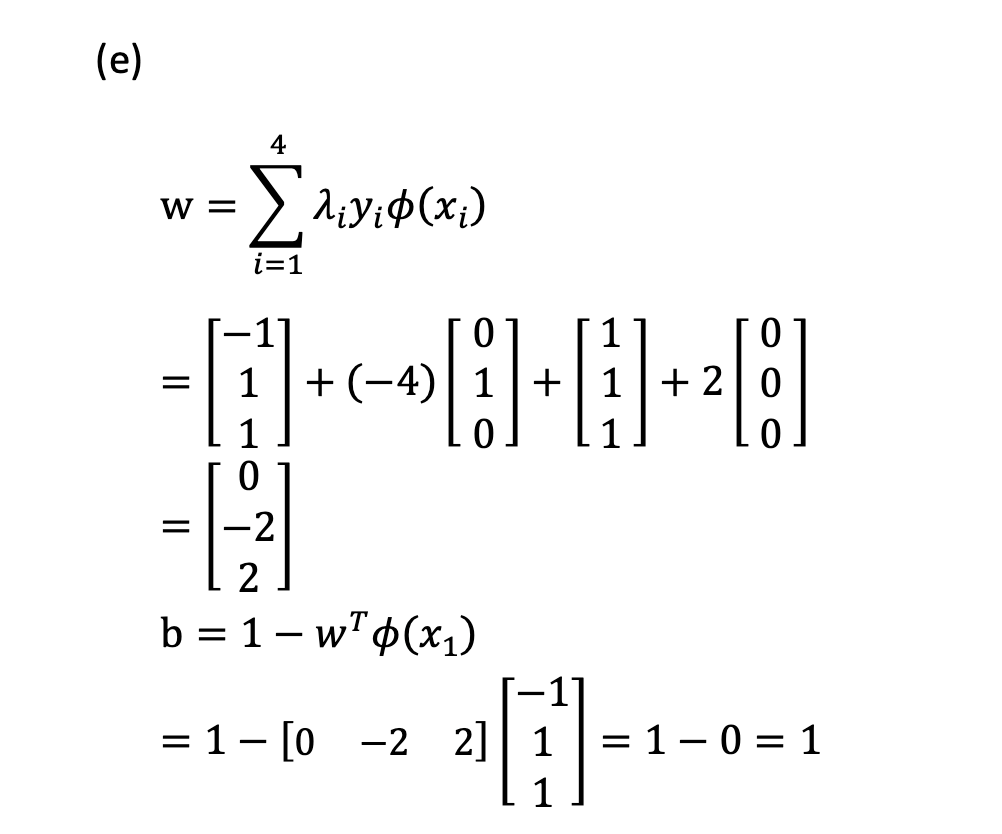

(f)

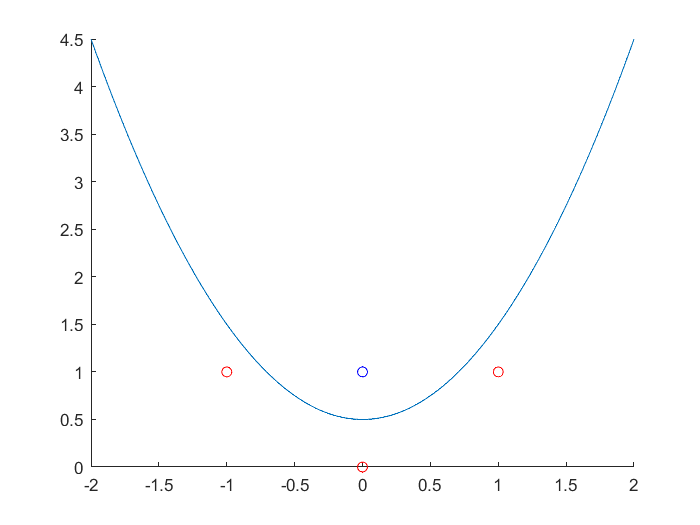

clear;
x1 = [-1 1 0;1 1 0]; 
x2 = [0;1];
t = linspace(-2,2,1000);
hold on;
plot(t,t.^2+1/2); 
scatter(x1(1,:),x1(2,:),'r');
scatter(x2(1,:),x2(2,:),'b');
hold off;

## Problem 2

(a)

clear;
load('07HW2_digit.mat');
%soft-margin SVM classifier and an RBF kernel
ga = [2^(-14) 2^(-12) 2^(-10) 2^(-8) 2^(-6)];
c = [2^(-5) 2^(-3) 2^(-1) 2^1 2^3];
train = [train0;train1];
test = [test0;test1];
train=double(train)/256;
test=double(test)/256;
g = [zeros(500,1);ones(500,1)];
test_g = [zeros(100,1);ones(100,1)];

for i = 1:size(ga,2)
    for j = 1:size(c,2)
        options1 = ['-g ',num2str(ga(i)),' -c ',num2str(c(j))];
        model1 = svmtrain(g,train,options1);
        [pGROUP Accuracy p_val] = svmpredict(test_g,test,model1);
        Accuracy_RBF(i,j) = Accuracy(1,1);
    end
end

*
optimization finished, #iter = 500
nu = 1.000000
obj = -30.354380, rho = -0.002872
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -110.670075, rho = -0.011490
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 442
nu = 0.880258
obj = -280.682735, rho = -0.177078
nSV = 882, nBSV = 880
Total nSV = 882


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 209
nu = 0.390075
obj = -474.038791, rho = -0.453125
nSV = 394, nBSV = 386
Total nSV = 394


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 101
nu = 0.158999
obj = -771.754150, rho = -0.673960
nSV = 165, nBSV = 153
Total nSV = 165


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -27.728395, rho = -0.012576
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 444
nu = 0.887441
obj = -70.831043, rho = -0.176147
nSV = 888, nBSV = 886
Total nSV = 888


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 211
nu = 0.393835
obj = -119.597441, rho = -0.453442
nSV = 401, nBSV = 389
Total nSV = 401


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 102
nu = 0.160131
obj = -194.508197, rho = -0.663722
nSV = 165, nBSV = 155
Total nSV = 165


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 100
nu = 0.064617
obj = -305.748717, rho = -0.764388
nSV = 78, nBSV = 53
Total nSV = 78


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 461
nu = 0.921019
obj = -18.382455, rho = -0.174068
nSV = 922, nBSV = 920
Total nSV = 922


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 221
nu = 0.409679
obj = -31.022080, rho = -0.443276
nSV = 417, nBSV = 403
Total nSV = 417


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 98
nu = 0.165056
obj = -50.229214, rho = -0.636741
nSV = 169, nBSV = 161
Total nSV = 169


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 105
nu = 0.066544
obj = -78.803095, rho = -0.744728
nSV = 81, nBSV = 53
Total nSV = 81


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 157
nu = 0.025277
obj = -114.000909, rho = -0.699111
nSV = 50, nBSV = 11
Total nSV = 50


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 243
nu = 0.479586
obj = -9.019351, rho = -0.437737
nSV = 482, nBSV = 476
Total nSV = 482


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 114
nu = 0.190598
obj = -14.357868, rho = -0.606057
nSV = 198, nBSV = 183
Total nSV = 198


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 103
nu = 0.075892
obj = -22.383566, rho = -0.697341
nSV = 92, nBSV = 61
Total nSV = 92


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 138
nu = 0.028725
obj = -31.807226, rho = -0.598893
nSV = 58, nBSV = 11
Total nSV = 58


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 147
nu = 0.009172
obj = -39.454415, rho = -0.596455
nSV = 50, nBSV = 1
Total nSV = 50


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 205
nu = 0.348485
obj = -6.385091, rho = -0.602705
nSV = 364, nBSV = 333
Total nSV = 364


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 130
nu = 0.131768
obj = -9.637319, rho = -0.649530
nSV = 156, nBSV = 115
Total nSV = 156


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 144
nu = 0.049927
obj = -13.854049, rho = -0.584468
nSV = 92, nBSV = 24
Total nSV = 92


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 201
nu = 0.015704
obj = -16.365030, rho = -0.519875
nSV = 95, nBSV = 1
Total nSV = 95


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 201
nu = 0.004244
obj = -16.976162, rho = -0.512311
nSV = 96, nBSV = 0
Total nSV = 96


Accuracy = 100% (200/200) (classification)


%find best gamma and c 
best_a=0;
for i=1:size(Accuracy_RBF,1)
    for j=1:size(Accuracy_RBF,2)
        if Accuracy_RBF (i,j)>best_a
            best_a=Accuracy_RBF (i,j);
            b_ga=log2(ga(i));
            b_c=log2(c(j));
        end
    end
end
fprintf('beat gamma = 2^%s \nbeat c = 2^%s',num2str(b_ga),num2str(b_c));

beat gamma = 2^-14 
beat c = 2^3

(b)


for i = 1:size(ga,2)
    for j = 1:size(c,2)
        % linear
        options2 = ['-t 0 -g ',num2str(ga(i)),' -c ',num2str(c(j))];
        model2 = svmtrain(g,train,options2);
        [pGROUP Accuracy2 p_val] = svmpredict(test_g,test,model2);
        Accuracy_l((i),(j)) = Accuracy2(1,1);
        % polynomial,p = 1
        options3 = ['-t 1 -d 1 -r 1 -g ',num2str(ga(i)),' -c ',num2str(c(j))];
        model3 = svmtrain(g,train,options3);
        [pGROUP Accuracy3 p_val] = svmpredict(test_g,test,model3);
        Accuracy_p1((i),(j)) = Accuracy3(1,1);
        % polynomial,p = 2
        options4 = ['-t 1 -d 2 -r 1 -g ',num2str(ga(i)),' -c ',num2str(c(j))];
        model4 = svmtrain(g,train,options4);
        [pGROUP Accuracy4 p_val] = svmpredict(test_g,test,model4);
        Accuracy_p2((i),(j))=Accuracy4(1,1);
        % polynomial,p = 3
        options5 = ['-t 1 -d 3 -r 1 -g ',num2str(ga(i)),' -c ',num2str(c(j))];
        model5 = svmtrain(g,train,options5);
        [pGROUP Accuracy5 p_val] = svmpredict(test_g,test,model5);
        Accuracy_p3((i),(j)) = Accuracy5(1,1);
    end
end

*
optimization finished, #iter = 162
nu = 0.014489
obj = -0.251615, rho = 0.381528
nSV = 40, nBSV = 5
Total nSV = 40


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -30.799620, rho = 0.031072
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -30.346579, rho = 0.062464
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -29.890862, rho = 0.094179
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 93.5% (187/200) (classification)


*
optimization finished, #iter = 148
nu = 0.004959
obj = -0.309909, rho = 0.525408
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -117.793927, rho = 0.124288
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -110.545270, rho = 0.249856
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -103.253792, rho = 0.376717
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 93.5% (187/200) (classification)


*
optimization finished, #iter = 146
nu = 0.001240
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -384.702834, rho = 0.497150
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 439
nu = 0.875960
obj = -279.380185, rho = 0.664031
nSV = 876, nBSV = 874
Total nSV = 876


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 360
nu = 0.708342
obj = -219.496226, rho = 0.659938
nSV = 710, nBSV = 707
Total nSV = 710


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000310
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 308
nu = 0.599674
obj = -736.310325, rho = 0.650604
nSV = 603, nBSV = 596
Total nSV = 603


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 209
nu = 0.388209
obj = -471.976996, rho = 0.612108
nSV = 392, nBSV = 383
Total nSV = 392


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 166
nu = 0.299032
obj = -362.654710, rho = 0.599140
nSV = 304, nBSV = 293
Total nSV = 304


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000077
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 140
nu = 0.249534
obj = -1205.447200, rho = 0.576413
nSV = 256, nBSV = 245
Total nSV = 256


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 101
nu = 0.158489
obj = -768.790870, rho = 0.552748
nSV = 165, nBSV = 153
Total nSV = 165


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 80
nu = 0.122660
obj = -588.132603, rho = 0.541395
nSV = 128, nBSV = 116
Total nSV = 128


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 162
nu = 0.014489
obj = -0.251615, rho = 0.381528
nSV = 40, nBSV = 5
Total nSV = 40


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -29.448482, rho = 0.124288
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -27.604379, rho = 0.253700
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 93% (186/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -25.716748, rho = 0.388407
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 92.5% (185/200) (classification)


*
optimization finished, #iter = 148
nu = 0.004959
obj = -0.309909, rho = 0.525408
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -96.175707, rho = 0.497150
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 439
nu = 0.871984
obj = -69.526783, rho = 0.666272
nSV = 873, nBSV = 870
Total nSV = 873


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 355
nu = 0.701625
obj = -54.380604, rho = 0.660949
nSV = 703, nBSV = 699
Total nSV = 703


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 146
nu = 0.001240
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 307
nu = 0.599615
obj = -184.077556, rho = 0.650577
nSV = 603, nBSV = 596
Total nSV = 603


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 203
nu = 0.386407
obj = -117.534386, rho = 0.611949
nSV = 391, nBSV = 382
Total nSV = 391


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 166
nu = 0.296687
obj = -89.999478, rho = 0.599169
nSV = 302, nBSV = 292
Total nSV = 302


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000310
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.249541
obj = -301.361856, rho = 0.576361
nSV = 256, nBSV = 245
Total nSV = 256


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 102
nu = 0.158089
obj = -191.539153, rho = 0.553201
nSV = 165, nBSV = 152
Total nSV = 165


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 77
nu = 0.121838
obj = -146.004088, rho = 0.538170
nSV = 128, nBSV = 116
Total nSV = 128


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000077
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 96
nu = 0.101951
obj = -485.037283, rho = 0.486824
nSV = 114, nBSV = 90
Total nSV = 114


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 79
nu = 0.063829
obj = -301.298879, rho = 0.437999
nSV = 77, nBSV = 55
Total nSV = 77


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 92
nu = 0.047777
obj = -226.273353, rho = 0.403893
nSV = 65, nBSV = 35
Total nSV = 65


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 162
nu = 0.014489
obj = -0.251615, rho = 0.381528
nSV = 40, nBSV = 5
Total nSV = 40


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 500
nu = 1.000000
obj = -24.043927, rho = 0.497150
nSV = 1000, nBSV = 1000
Total nSV = 1000


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 429
nu = 0.855642
obj = -17.075267, rho = 0.671361
nSV = 856, nBSV = 854
Total nSV = 856


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 340
nu = 0.676000
obj = -13.125851, rho = 0.665855
nSV = 677, nBSV = 675
Total nSV = 677


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 148
nu = 0.004959
obj = -0.309909, rho = 0.525408
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 308
nu = 0.599675
obj = -46.019390, rho = 0.650603
nSV = 603, nBSV = 596
Total nSV = 603


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 204
nu = 0.380021
obj = -28.938503, rho = 0.613458
nSV = 386, nBSV = 376
Total nSV = 386


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 158
nu = 0.288122
obj = -21.861511, rho = 0.600997
nSV = 292, nBSV = 282
Total nSV = 292


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 146
nu = 0.001240
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.249549
obj = -75.340460, rho = 0.576430
nSV = 256, nBSV = 245
Total nSV = 256


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 102
nu = 0.155957
obj = -47.242209, rho = 0.553886
nSV = 165, nBSV = 149
Total nSV = 165


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 86
nu = 0.118492
obj = -35.508801, rho = 0.530757
nSV = 127, nBSV = 110
Total nSV = 127


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000310
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 96
nu = 0.101951
obj = -121.259243, rho = 0.486823
nSV = 114, nBSV = 90
Total nSV = 114


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 86
nu = 0.062998
obj = -74.312306, rho = 0.437673
nSV = 76, nBSV = 54
Total nSV = 76


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 95
nu = 0.046765
obj = -54.980659, rho = 0.398072
nSV = 64, nBSV = 34
Total nSV = 64


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000077
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 67
nu = 0.040595
obj = -186.557104, rho = 0.373622
nSV = 55, nBSV = 31
Total nSV = 55


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 124
nu = 0.023840
obj = -107.626733, rho = 0.353014
nSV = 47, nBSV = 12
Total nSV = 47


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 156
nu = 0.017102
obj = -75.518181, rho = 0.363966
nSV = 42, nBSV = 5
Total nSV = 42


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 162
nu = 0.014489
obj = -0.251615, rho = 0.381528
nSV = 40, nBSV = 5
Total nSV = 40


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 307
nu = 0.599609
obj = -11.504736, rho = 0.650578
nSV = 603, nBSV = 596
Total nSV = 603


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 188
nu = 0.356932
obj = -6.842035, rho = 0.622951
nSV = 360, nBSV = 354
Total nSV = 360


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 151
nu = 0.257452
obj = -4.915399, rho = 0.613492
nSV = 264, nBSV = 253
Total nSV = 264


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 148
nu = 0.004959
obj = -0.309909, rho = 0.525408
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 140
nu = 0.249532
obj = -18.834925, rho = 0.576414
nSV = 256, nBSV = 245
Total nSV = 256


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 98
nu = 0.148646
obj = -11.227717, rho = 0.551553
nSV = 157, nBSV = 140
Total nSV = 157


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 101
nu = 0.107208
obj = -8.038865, rho = 0.508900
nSV = 118, nBSV = 95
Total nSV = 118


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.001240
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 96
nu = 0.101950
obj = -30.314495, rho = 0.486820
nSV = 114, nBSV = 90
Total nSV = 114


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 77
nu = 0.060378
obj = -17.684821, rho = 0.436912
nSV = 71, nBSV = 48
Total nSV = 71


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 100
nu = 0.043015
obj = -12.227638, rho = 0.392811
nSV = 61, nBSV = 28
Total nSV = 61


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000310
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 67
nu = 0.040594
obj = -46.638743, rho = 0.373620
nSV = 55, nBSV = 31
Total nSV = 55


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 115
nu = 0.022558
obj = -24.876628, rho = 0.356264
nSV = 46, nBSV = 9
Total nSV = 46


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 166
nu = 0.014731
obj = -15.636280, rho = 0.404370
nSV = 47, nBSV = 2
Total nSV = 47


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000077
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 163
nu = 0.014488
obj = -64.412782, rho = 0.381645
nSV = 40, nBSV = 5
Total nSV = 40


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 149
nu = 0.007224
obj = -30.704399, rho = 0.447540
nSV = 43, nBSV = 1
Total nSV = 43


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 151
nu = 0.004268
obj = -17.070675, rho = 0.432857
nSV = 46, nBSV = 0
Total nSV = 46


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 162
nu = 0.014489
obj = -0.251615, rho = 0.381528
nSV = 40, nBSV = 5
Total nSV = 40


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 140
nu = 0.249534
obj = -4.708771, rho = 0.576412
nSV = 256, nBSV = 245
Total nSV = 256


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 109
nu = 0.126499
obj = -2.393901, rho = 0.523368
nSV = 141, nBSV = 114
Total nSV = 141


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 78
nu = 0.079409
obj = -1.475256, rho = 0.555230
nSV = 96, nBSV = 70
Total nSV = 96


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 148
nu = 0.004959
obj = -0.309909, rho = 0.525408
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 96
nu = 0.101951
obj = -7.578690, rho = 0.486822
nSV = 114, nBSV = 90
Total nSV = 114


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 92
nu = 0.052021
obj = -3.720472, rho = 0.452554
nSV = 68, nBSV = 38
Total nSV = 68


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 121
nu = 0.029966
obj = -2.018348, rho = 0.461428
nSV = 58, nBSV = 14
Total nSV = 58


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.001240
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 67
nu = 0.040594
obj = -11.659797, rho = 0.373620
nSV = 55, nBSV = 31
Total nSV = 55


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 144
nu = 0.018289
obj = -4.836318, rho = 0.404847
nSV = 47, nBSV = 4
Total nSV = 47


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 141
nu = 0.008721
obj = -2.180128, rho = 0.469800
nSV = 50, nBSV = 0
Total nSV = 50


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000310
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 162
nu = 0.014489
obj = -16.103358, rho = 0.381528
nSV = 40, nBSV = 5
Total nSV = 40


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 143
nu = 0.005263
obj = -5.262794, rho = 0.428541
nSV = 46, nBSV = 0
Total nSV = 46


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 141
nu = 0.002180
obj = -2.180128, rho = 0.469800
nSV = 50, nBSV = 0
Total nSV = 50


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000077
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 148
nu = 0.004959
obj = -19.834179, rho = 0.525408
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 143
nu = 0.001316
obj = -5.262794, rho = 0.428541
nSV = 46, nBSV = 0
Total nSV = 46


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 141
nu = 0.000545
obj = -2.180128, rho = 0.469800
nSV = 50, nBSV = 0
Total nSV = 50


Accuracy = 100% (200/200) (classification)


disp(Accuracy_l);

   100   100   100   100   100
   100   100   100   100   100
   100   100   100   100   100
   100   100   100   100   100
   100   100   100   100   100



disp(Accuracy_p1);

    94    94    94    99   100
    94    94    99   100   100
    94    99   100   100   100
    99   100   100   100   100
   100   100   100   100   100



disp(Accuracy_p2);

   94.0000   94.0000   98.5000   99.5000  100.0000
   93.0000   98.5000   99.5000  100.0000  100.0000
   98.5000   99.5000  100.0000  100.0000  100.0000
   99.5000  100.0000  100.0000  100.0000  100.0000
  100.0000  100.0000  100.0000  100.0000  100.0000



disp(Accuracy_p3);

   93.5000   93.5000   99.0000   99.5000  100.0000
   92.5000   99.0000   99.5000  100.0000  100.0000
   99.0000   99.5000  100.0000  100.0000  100.0000
   99.5000  100.0000  100.0000  100.0000  100.0000
  100.0000  100.0000  100.0000  100.0000  100.0000



由結果可看出linear kernal的accuracy最高，而polynomial kernal在c與gamma較小時的accuracy隨著degree上升而下降。

## **(c)**

ga = num2str(2^(-8)); 
c = num2str(2^3);
Accuracy_RBF = 0; 
Accuracy_l = 0; 
Accuracy_p1 = 0;
Accuracy_p2 = 0;
Accuracy_p3 = 0;
train_d = [train0;train1;train2;train3;train4;train5;train6;train7;train8;train9];
test_d = [test0;test1;test2;test3;test4;test5;test6;test7;test8;test9];
train_d = double(train_d)/256;
test_d = double(test_d)/256;
test_dg = [zeros(100,1);ones(100,1);ones(100,1)*2;ones(100,1)*3;ones(100,1)*4;ones(100,1)*5;ones(100,1)*6;ones(100,1)*7;ones(100,1)*8;ones(100,1)*9];
g = [zeros(500,1);ones(500,1);ones(500,1)*2;ones(500,1)*3;ones(500,1)*4;ones(500,1)*5;ones(500,1)*6;ones(500,1)*7;ones(500,1)*8;ones(500,1)*9];

% RBF
options1 = ['-g ',ga,' -c ',c];

% linear
options2 = ['-t 0 -g ',ga,' -c ',c];

% polynomial,p = 1
options3 = ['-t 1 -d 1 -r 1 -g ',ga,' -c ',c];

% polynomial,p = 2
options4 = ['-t 1 -d 2 -r 1 -g ',ga,' -c ',c];

% polynomial,p = 3
options5 = ['-t 1 -d 3 -r 1 -g ',ga,' -c ',c];

for i = 1:9
    for j = i:9
        train = [train_d((i-1)*500+1:i*500,:);train_d(j*500+1:(j+1)*500,:)];
        train_g = [g((i-1)*500+1:i*500);g(j*500+1:(j+1)*500)];
        test = [test_d((i-1)*100+1:i*100,:);test_d(j*100+1:(j+1)*100,:)];
        test_g = [test_dg((i-1)*100+1:i*100,:);test_dg(j*100+1:(j+1)*100,:)];
        
        % RBF
        model1 = svmtrain(train_g,train,options1);
        [pGROUP Accuracy p_val] = svmpredict(test_g,test,model1);
        A(i,j) = Accuracy(1,1);
        Accuracy_RBF = Accuracy_RBF + Accuracy(1,1)/45;
        % linear
        model2 = svmtrain(train_g,train,options2);
        [pGROUP Accuracy2 p_val] = svmpredict(test_g,test,model2);
        B(i,j) = Accuracy2(1,1);
        Accuracy_l = Accuracy_l + Accuracy2(1,1)/45;
        % polynomial,p = 1
        model3 = svmtrain(train_g,train,options3);
        [pGROUP Accuracy3 p_val] = svmpredict(test_g,test,model3);
        C(i,j) = Accuracy3(1,1);
        Accuracy_p1 = Accuracy_p1 + Accuracy3(1,1)/45;
        % polynomial,p = 2
        model4 = svmtrain(train_g,train,options4);
        [pGROUP Accuracy4 p_val] = svmpredict(test_g,test,model4);
        C(i,j) = Accuracy4(1,1);
        Accuracy_p2 = Accuracy_p2 + Accuracy4(1,1)/45;
        % polynomial,p = 3
        model5 = svmtrain(train_g,train,options5);
        [pGROUP Accuracy5 p_val] = svmpredict(test_g,test,model5);
        C(i,j) = Accuracy5(1,1);
        Accuracy_p3 = Accuracy_p3 + Accuracy5(1,1)/45;
    end
end

*
optimization finished, #iter = 147
nu = 0.009172
obj = -39.454415, rho = -0.596455
nSV = 50, nBSV = 1
Total nSV = 50


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 146
nu = 0.000077
obj = -0.309909, rho = 0.525427
nSV = 37, nBSV = 0
Total nSV = 37


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 163
nu = 0.014488
obj = -64.412782, rho = 0.381645
nSV = 40, nBSV = 5
Total nSV = 40


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 149
nu = 0.007224
obj = -30.704399, rho = 0.447540
nSV = 43, nBSV = 1
Total nSV = 43


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 151
nu = 0.004268
obj = -17.070675, rho = 0.432857
nSV = 46, nBSV = 0
Total nSV = 46


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 465
nu = 0.039515
obj = -166.941445, rho = 0.519310
nSV = 112, nBSV = 4
Total nSV = 112


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 845
nu = 0.000542
obj = -2.167868, rho = 0.636063
nSV = 82, nBSV = 0
Total nSV = 82


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 400
nu = 0.063644
obj = -325.157882, rho = 0.314333
nSV = 95, nBSV = 36
Total nSV = 95


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 497
nu = 0.033185
obj = -142.008805, rho = 0.318388
nSV = 91, nBSV = 3
Total nSV = 91


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 524
nu = 0.017143
obj = -68.987980, rho = 0.204218
nSV = 102, nBSV = 1
Total nSV = 102


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 385
nu = 0.028315
obj = -119.458347, rho = 0.274978
nSV = 94, nBSV = 3
Total nSV = 94


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 610
nu = 0.000279
obj = -1.115761, rho = 0.253247
nSV = 72, nBSV = 0
Total nSV = 72


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 425
nu = 0.044615
obj = -208.198342, rho = 0.145030
nSV = 84, nBSV = 19
Total nSV = 84


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 411
nu = 0.021572
obj = -91.775939, rho = 0.138987
nSV = 78, nBSV = 2
Total nSV = 78


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 395
nu = 0.011909
obj = -47.635129, rho = 0.185964
nSV = 85, nBSV = 0
Total nSV = 85


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 345
nu = 0.017839
obj = -72.571601, rho = -0.245642
nSV = 88, nBSV = 1
Total nSV = 88


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 364
nu = 0.000133
obj = -0.533745, rho = 0.518203
nSV = 61, nBSV = 0
Total nSV = 61


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 337
nu = 0.028732
obj = -125.885252, rho = 0.513302
nSV = 65, nBSV = 9
Total nSV = 65


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 352
nu = 0.013169
obj = -52.678042, rho = 0.447703
nSV = 69, nBSV = 0
Total nSV = 69


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 308
nu = 0.007006
obj = -28.024822, rho = 0.433897
nSV = 78, nBSV = 0
Total nSV = 78


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 518
nu = 0.042888
obj = -180.150684, rho = 0.248924
nSV = 116, nBSV = 4
Total nSV = 116


Accuracy = 99.5% (199/200) (classification)


*.*
optimization finished, #iter = 1092
nu = 0.000493
obj = -1.973763, rho = 1.159430
nSV = 94, nBSV = 0
Total nSV = 94


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 501
nu = 0.072573
obj = -348.828653, rho = 0.983555
nSV = 106, nBSV = 45
Total nSV = 106


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 641
nu = 0.034905
obj = -147.548847, rho = 0.905071
nSV = 101, nBSV = 4
Total nSV = 101


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 596
nu = 0.018277
obj = -73.110786, rho = 0.907956
nSV = 114, nBSV = 0
Total nSV = 114


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 433
nu = 0.032723
obj = -145.063824, rho = 0.026715
nSV = 101, nBSV = 6
Total nSV = 101


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 596
nu = 0.000386
obj = -1.543080, rho = 0.835701
nSV = 66, nBSV = 0
Total nSV = 66


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 438
nu = 0.049593
obj = -241.089688, rho = 0.493218
nSV = 86, nBSV = 24
Total nSV = 86


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 494
nu = 0.026309
obj = -117.211098, rho = 0.482371
nSV = 85, nBSV = 5
Total nSV = 85


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 440
nu = 0.015319
obj = -61.276384, rho = 0.493773
nSV = 90, nBSV = 0
Total nSV = 90


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 285
nu = 0.022054
obj = -89.659549, rho = 0.040383
nSV = 76, nBSV = 3
Total nSV = 76


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 391
nu = 0.000178
obj = -0.711347, rho = 0.780086
nSV = 57, nBSV = 0
Total nSV = 57


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 292
nu = 0.034253
obj = -156.452395, rho = 0.656813
nSV = 69, nBSV = 15
Total nSV = 69


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 305
nu = 0.016919
obj = -68.135842, rho = 0.664971
nSV = 64, nBSV = 1
Total nSV = 64


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 308
nu = 0.008845
obj = -35.379943, rho = 0.592371
nSV = 72, nBSV = 0
Total nSV = 72


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 393
nu = 0.023318
obj = -99.603834, rho = -0.166947
nSV = 101, nBSV = 2
Total nSV = 101


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 524
nu = 0.000257
obj = -1.028312, rho = -0.340331
nSV = 65, nBSV = 0
Total nSV = 65


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 446
nu = 0.039340
obj = -176.285790, rho = -0.194906
nSV = 77, nBSV = 14
Total nSV = 77


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 432
nu = 0.017374
obj = -76.130425, rho = -0.158913
nSV = 84, nBSV = 2
Total nSV = 84


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 436
nu = 0.010143
obj = -41.852295, rho = -0.078225
nSV = 91, nBSV = 1
Total nSV = 91


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 403
nu = 0.028568
obj = -126.173706, rho = -0.055591
nSV = 98, nBSV = 5
Total nSV = 98


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 787
nu = 0.000316
obj = -1.264206, rho = 0.486068
nSV = 75, nBSV = 0
Total nSV = 75


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 440
nu = 0.042010
obj = -207.342827, rho = 0.240153
nSV = 88, nBSV = 20
Total nSV = 88


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 552
nu = 0.022656
obj = -100.193634, rho = 0.228762
nSV = 85, nBSV = 4
Total nSV = 85


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 445
nu = 0.013035
obj = -52.142698, rho = 0.239739
nSV = 91, nBSV = 0
Total nSV = 91


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 382
nu = 0.046291
obj = -210.666768, rho = 0.767044
nSV = 94, nBSV = 14
Total nSV = 94


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 899
nu = 0.000734
obj = -2.936291, rho = -0.126297
nSV = 82, nBSV = 0
Total nSV = 82


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 255
nu = 0.068713
obj = -354.552424, rho = -0.209080
nSV = 92, nBSV = 47
Total nSV = 92


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 453
nu = 0.041007
obj = -189.837478, rho = -0.266059
nSV = 88, nBSV = 12
Total nSV = 88


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 452
nu = 0.025942
obj = -113.058213, rho = -0.335219
nSV = 96, nBSV = 3
Total nSV = 96


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 306
nu = 0.041450
obj = -189.507228, rho = 1.055169
nSV = 85, nBSV = 16
Total nSV = 85


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 614
nu = 0.000484
obj = -1.936327, rho = 0.154396
nSV = 69, nBSV = 0
Total nSV = 69


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 375
nu = 0.059739
obj = -308.942836, rho = 0.091518
nSV = 87, nBSV = 36
Total nSV = 87


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 299
nu = 0.036505
obj = -165.621905, rho = -0.018269
nSV = 78, nBSV = 14
Total nSV = 78


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 339
nu = 0.022824
obj = -93.713906, rho = -0.117254
nSV = 76, nBSV = 2
Total nSV = 76


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 199
nu = 0.027797
obj = -126.325454, rho = -0.475082
nSV = 60, nBSV = 11
Total nSV = 60


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 244
nu = 0.000312
obj = -1.249049, rho = -0.014503
nSV = 43, nBSV = 0
Total nSV = 43


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 240
nu = 0.039071
obj = -194.923628, rho = -0.009857
nSV = 64, nBSV = 23
Total nSV = 64


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 258
nu = 0.024008
obj = -108.589130, rho = -0.075473
nSV = 55, nBSV = 8
Total nSV = 55


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 181
nu = 0.015598
obj = -67.032744, rho = -0.164433
nSV = 48, nBSV = 3
Total nSV = 48


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 324
nu = 0.031703
obj = -135.309735, rho = 1.182983
nSV = 86, nBSV = 6
Total nSV = 86


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 505
nu = 0.000295
obj = -1.178103, rho = 0.047544
nSV = 70, nBSV = 0
Total nSV = 70


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 279
nu = 0.049407
obj = -235.659213, rho = 0.178296
nSV = 77, nBSV = 25
Total nSV = 77


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 403
nu = 0.027290
obj = -115.386233, rho = 0.055965
nSV = 78, nBSV = 6
Total nSV = 78


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 329
nu = 0.016092
obj = -65.039702, rho = 0.032514
nSV = 77, nBSV = 1
Total nSV = 77


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 208
nu = 0.024971
obj = -104.763970, rho = 0.136038
nSV = 64, nBSV = 7
Total nSV = 64


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 281
nu = 0.000213
obj = -0.851637, rho = -0.476161
nSV = 48, nBSV = 0
Total nSV = 48


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 212
nu = 0.037399
obj = -176.408072, rho = -0.266648
nSV = 66, nBSV = 23
Total nSV = 66


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 240
nu = 0.020618
obj = -84.680360, rho = -0.442980
nSV = 57, nBSV = 4
Total nSV = 57


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 253
nu = 0.011577
obj = -46.313321, rho = -0.492509
nSV = 61, nBSV = 0
Total nSV = 61


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 222
nu = 0.044434
obj = -205.085213, rho = 0.286420
nSV = 72, nBSV = 19
Total nSV = 72


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 511
nu = 0.000485
obj = -1.940464, rho = -0.436069
nSV = 62, nBSV = 0
Total nSV = 62


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 160
nu = 0.061315
obj = -319.264746, rho = -0.258716
nSV = 82, nBSV = 48
Total nSV = 82


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 349
nu = 0.039071
obj = -177.740523, rho = -0.356492
nSV = 70, nBSV = 16
Total nSV = 70


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 346
nu = 0.025600
obj = -104.708425, rho = -0.506580
nSV = 71, nBSV = 4
Total nSV = 71


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 417
nu = 0.063377
obj = -293.834704, rho = -0.431552
nSV = 107, nBSV = 31
Total nSV = 107


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 918
nu = 0.001139
obj = -4.556134, rho = -1.024696
nSV = 83, nBSV = 0
Total nSV = 83


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 349
nu = 0.091773
obj = -511.826538, rho = -0.673848
nSV = 122, nBSV = 68
Total nSV = 122


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 489
nu = 0.059164
obj = -278.430913, rho = -0.759889
nSV = 99, nBSV = 28
Total nSV = 99


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 578
nu = 0.034996
obj = -146.649376, rho = -0.841934
nSV = 96, nBSV = 5
Total nSV = 96


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 249
nu = 0.030513
obj = -141.466841, rho = -0.076271
nSV = 75, nBSV = 14
Total nSV = 75


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 382
nu = 0.000376
obj = -1.504840, rho = 0.009446
nSV = 60, nBSV = 0
Total nSV = 60


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 245
nu = 0.043510
obj = -221.390836, rho = -0.112040
nSV = 69, nBSV = 25
Total nSV = 69


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 276
nu = 0.026489
obj = -121.523968, rho = -0.076151
nSV = 66, nBSV = 10
Total nSV = 66


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 326
nu = 0.016800
obj = -70.896884, rho = -0.222445
nSV = 68, nBSV = 2
Total nSV = 68


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 797
nu = 0.081660
obj = -368.647252, rho = -0.070594
nSV = 167, nBSV = 26
Total nSV = 167


Accuracy = 98.5% (197/200) (classification)


.*.*
optimization finished, #iter = 2128
nu = 0.001470
obj = -5.880202, rho = -0.573200
nSV = 126, nBSV = 0
Total nSV = 126


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 834
nu = 0.119824
obj = -658.704235, rho = -0.683018
nSV = 163, nBSV = 80
Total nSV = 163


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 993
nu = 0.072555
obj = -334.654323, rho = -0.301665
nSV = 151, nBSV = 25
Total nSV = 151


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 972
nu = 0.039708
obj = -160.916458, rho = -0.126791
nSV = 154, nBSV = 3
Total nSV = 154


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 520
nu = 0.058350
obj = -259.644758, rho = -1.192032
nSV = 127, nBSV = 14
Total nSV = 127


Accuracy = 98% (196/200) (classification)


*.*
optimization finished, #iter = 1287
nu = 0.000887
obj = -3.547733, rho = 0.450892
nSV = 101, nBSV = 0
Total nSV = 101


Accuracy = 96.5% (193/200) (classification)


*
optimization finished, #iter = 465
nu = 0.084065
obj = -448.054985, rho = 0.303700
nSV = 117, nBSV = 51
Total nSV = 117


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 673
nu = 0.051754
obj = -233.191550, rho = 0.352247
nSV = 118, nBSV = 11
Total nSV = 118


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 667
nu = 0.029397
obj = -123.258621, rho = 0.318871
nSV = 123, nBSV = 4
Total nSV = 123


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 583
nu = 0.058588
obj = -256.115002, rho = -0.532768
nSV = 140, nBSV = 12
Total nSV = 140


Accuracy = 98.5% (197/200) (classification)


*.*
optimization finished, #iter = 1246
nu = 0.000886
obj = -3.545513, rho = 0.875197
nSV = 108, nBSV = 0
Total nSV = 108


Accuracy = 96% (192/200) (classification)


*
optimization finished, #iter = 612
nu = 0.093789
obj = -489.608548, rho = 0.824280
nSV = 134, nBSV = 60
Total nSV = 134


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 807
nu = 0.052255
obj = -232.284405, rho = 0.711612
nSV = 128, nBSV = 8
Total nSV = 128


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 687
nu = 0.029313
obj = -117.818700, rho = 0.590196
nSV = 129, nBSV = 1
Total nSV = 129


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 651
nu = 0.063937
obj = -275.622592, rho = -1.218260
nSV = 144, nBSV = 16
Total nSV = 144


Accuracy = 98% (196/200) (classification)


*.*
optimization finished, #iter = 1612
nu = 0.000914
obj = -3.655700, rho = -0.598289
nSV = 116, nBSV = 0
Total nSV = 116


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 704
nu = 0.101334
obj = -536.065859, rho = -0.123919
nSV = 143, nBSV = 65
Total nSV = 143


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 833
nu = 0.057621
obj = -251.600609, rho = -0.310591
nSV = 133, nBSV = 16
Total nSV = 133


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 725
nu = 0.030555
obj = -123.911715, rho = -0.317140
nSV = 132, nBSV = 1
Total nSV = 132


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 539
nu = 0.053956
obj = -249.421506, rho = -0.524566
nSV = 120, nBSV = 17
Total nSV = 120


Accuracy = 97.5% (195/200) (classification)


*.*
optimization finished, #iter = 1353
nu = 0.000884
obj = -3.537932, rho = 0.204048
nSV = 102, nBSV = 0
Total nSV = 102


Accuracy = 95.5% (191/200) (classification)


*
optimization finished, #iter = 467
nu = 0.078414
obj = -409.571572, rho = 0.100420
nSV = 112, nBSV = 48
Total nSV = 112


Accuracy = 96% (192/200) (classification)


*
optimization finished, #iter = 571
nu = 0.047335
obj = -222.162173, rho = 0.066355
nSV = 108, nBSV = 14
Total nSV = 108


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 614
nu = 0.029464
obj = -124.109851, rho = -0.003713
nSV = 110, nBSV = 1
Total nSV = 110


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 795
nu = 0.089026
obj = -415.944551, rho = -1.953666
nSV = 179, nBSV = 34
Total nSV = 179


Accuracy = 96.5% (193/200) (classification)


.*.*
optimization finished, #iter = 2360
nu = 0.002329
obj = -9.317008, rho = -0.968602
nSV = 128, nBSV = 0
Total nSV = 128


Accuracy = 96% (192/200) (classification)


*
optimization finished, #iter = 757
nu = 0.126094
obj = -724.437926, rho = -0.853242
nSV = 177, nBSV = 90
Total nSV = 177


Accuracy = 96.5% (193/200) (classification)


*.*
optimization finished, #iter = 1013
nu = 0.082277
obj = -399.975334, rho = -0.806329
nSV = 158, nBSV = 34
Total nSV = 158


Accuracy = 95.5% (191/200) (classification)


*.*
optimization finished, #iter = 1085
nu = 0.048755
obj = -203.136509, rho = -0.534526
nSV = 157, nBSV = 6
Total nSV = 157


Accuracy = 96.5% (193/200) (classification)


*
optimization finished, #iter = 502
nu = 0.045648
obj = -200.311754, rho = -0.776193
nSV = 119, nBSV = 9
Total nSV = 119


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 907
nu = 0.000626
obj = -2.502395, rho = 0.466973
nSV = 90, nBSV = 0
Total nSV = 90


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 503
nu = 0.069891
obj = -356.343998, rho = 0.322108
nSV = 111, nBSV = 40
Total nSV = 111


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 678
nu = 0.039193
obj = -175.058100, rho = 0.309311
nSV = 103, nBSV = 9
Total nSV = 103


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 499
nu = 0.022281
obj = -90.539665, rho = 0.162073
nSV = 103, nBSV = 1
Total nSV = 103


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 324
nu = 0.035923
obj = -155.340888, rho = -1.156003
nSV = 90, nBSV = 8
Total nSV = 90


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 672
nu = 0.000358
obj = -1.432403, rho = 0.497368
nSV = 75, nBSV = 0
Total nSV = 75


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 324
nu = 0.053876
obj = -259.791402, rho = 0.334569
nSV = 82, nBSV = 28
Total nSV = 82


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 328
nu = 0.030342
obj = -131.153040, rho = 0.330663
nSV = 75, nBSV = 6
Total nSV = 75


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 394
nu = 0.018005
obj = -72.560960, rho = 0.335121
nSV = 88, nBSV = 1
Total nSV = 88


Accuracy = 100% (200/200) (classification)


*.*
optimization finished, #iter = 1006
nu = 0.122581
obj = -577.898916, rho = 0.694118
nSV = 231, nBSV = 61
Total nSV = 231


Accuracy = 98% (196/200) (classification)


..*..*
optimization finished, #iter = 4172
nu = 0.004235
obj = -16.943405, rho = 1.408717
nSV = 149, nBSV = 0
Total nSV = 149


Accuracy = 95.5% (191/200) (classification)


*
optimization finished, #iter = 630
nu = 0.180689
obj = -1063.771562, rho = 0.863327
nSV = 220, nBSV = 149
Total nSV = 220


Accuracy = 93.5% (187/200) (classification)


*.*
optimization finished, #iter = 1351
nu = 0.115386
obj = -573.682788, rho = 0.602001
nSV = 206, nBSV = 66
Total nSV = 206


Accuracy = 96.5% (193/200) (classification)


*.*
optimization finished, #iter = 1413
nu = 0.067715
obj = -279.183055, rho = 0.528409
nSV = 198, nBSV = 7
Total nSV = 198


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 390
nu = 0.029786
obj = -121.742723, rho = -0.675560
nSV = 95, nBSV = 5
Total nSV = 95


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 499
nu = 0.000249
obj = -0.997887, rho = 0.182006
nSV = 68, nBSV = 0
Total nSV = 68


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 354
nu = 0.047693
obj = -216.859661, rho = 0.315107
nSV = 83, nBSV = 21
Total nSV = 83


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 404
nu = 0.023388
obj = -94.733480, rho = 0.112953
nSV = 79, nBSV = 4
Total nSV = 79


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 405
nu = 0.012344
obj = -49.377106, rho = 0.039676
nSV = 87, nBSV = 0
Total nSV = 87


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 557
nu = 0.056580
obj = -270.385234, rho = -0.440826
nSV = 123, nBSV = 18
Total nSV = 123


Accuracy = 99% (198/200) (classification)


*.*
optimization finished, #iter = 1139
nu = 0.001039
obj = -4.156200, rho = 1.100978
nSV = 91, nBSV = 0
Total nSV = 91


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 442
nu = 0.079132
obj = -430.649726, rho = 0.536362
nSV = 109, nBSV = 51
Total nSV = 109


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 606
nu = 0.050772
obj = -246.309679, rho = 0.546673
nSV = 104, nBSV = 17
Total nSV = 104


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 620
nu = 0.032812
obj = -143.608108, rho = 0.607198
nSV = 112, nBSV = 7
Total nSV = 112


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 912
nu = 0.101769
obj = -465.608495, rho = -2.168474
nSV = 190, nBSV = 36
Total nSV = 190


Accuracy = 96% (192/200) (classification)


.*..*
optimization finished, #iter = 3150
nu = 0.002556
obj = -10.225285, rho = -1.226844
nSV = 136, nBSV = 0
Total nSV = 136


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 681
nu = 0.144410
obj = -813.772360, rho = -0.429024
nSV = 186, nBSV = 110
Total nSV = 186


Accuracy = 96.5% (193/200) (classification)


*.*
optimization finished, #iter = 1231
nu = 0.091483
obj = -435.212124, rho = -0.615290
nSV = 166, nBSV = 35
Total nSV = 166


Accuracy = 96.5% (193/200) (classification)


*.*
optimization finished, #iter = 1250
nu = 0.052537
obj = -221.383391, rho = -0.594563
nSV = 168, nBSV = 6
Total nSV = 168


Accuracy = 96% (192/200) (classification)


*
optimization finished, #iter = 526
nu = 0.066725
obj = -309.337755, rho = -1.063446
nSV = 137, nBSV = 25
Total nSV = 137


Accuracy = 99% (198/200) (classification)


*.*
optimization finished, #iter = 1280
nu = 0.001304
obj = -5.217067, rho = 0.571891
nSV = 101, nBSV = 0
Total nSV = 101


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 505
nu = 0.095743
obj = -530.481123, rho = 0.046655
nSV = 134, nBSV = 68
Total nSV = 134


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 662
nu = 0.060824
obj = -290.494638, rho = 0.110849
nSV = 126, nBSV = 27
Total nSV = 126


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 783
nu = 0.036370
obj = -150.720832, rho = 0.093092
nSV = 127, nBSV = 3
Total nSV = 127


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 504
nu = 0.052097
obj = -221.617304, rho = 0.641300
nSV = 123, nBSV = 10
Total nSV = 123


Accuracy = 99.5% (199/200) (classification)


*.*
optimization finished, #iter = 1109
nu = 0.000574
obj = -2.294824, rho = 0.599675
nSV = 97, nBSV = 0
Total nSV = 97


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 592
nu = 0.082921
obj = -410.961815, rho = 0.503218
nSV = 121, nBSV = 55
Total nSV = 121


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 669
nu = 0.045139
obj = -192.182763, rho = 0.476292
nSV = 109, nBSV = 7
Total nSV = 109


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 619
nu = 0.025114
obj = -102.554454, rho = 0.460384
nSV = 115, nBSV = 2
Total nSV = 115


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 456
nu = 0.044852
obj = -189.995208, rho = 0.179074
nSV = 115, nBSV = 13
Total nSV = 115


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 710
nu = 0.000474
obj = -1.896778, rho = -1.021824
nSV = 81, nBSV = 0
Total nSV = 81


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 463
nu = 0.066428
obj = -336.137300, rho = -0.422476
nSV = 108, nBSV = 45
Total nSV = 108


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 651
nu = 0.037826
obj = -158.811038, rho = -0.485212
nSV = 105, nBSV = 9
Total nSV = 105


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 564
nu = 0.020245
obj = -80.984666, rho = -0.453065
nSV = 107, nBSV = 0
Total nSV = 107


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 507
nu = 0.061922
obj = -288.863510, rho = 0.949167
nSV = 134, nBSV = 25
Total nSV = 134


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 851
nu = 0.000959
obj = -3.835890, rho = -0.269670
nSV = 88, nBSV = 0
Total nSV = 88


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 503
nu = 0.089353
obj = -469.406448, rho = -0.267203
nSV = 127, nBSV = 65
Total nSV = 127


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 569
nu = 0.054027
obj = -258.164545, rho = -0.231770
nSV = 115, nBSV = 26
Total nSV = 115


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 631
nu = 0.034595
obj = -145.803909, rho = -0.076567
nSV = 117, nBSV = 4
Total nSV = 117


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 424
nu = 0.043136
obj = -188.762807, rho = 0.209718
nSV = 113, nBSV = 12
Total nSV = 113


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 773
nu = 0.000443
obj = -1.770474, rho = -0.858397
nSV = 80, nBSV = 0
Total nSV = 80


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 385
nu = 0.063695
obj = -310.330109, rho = -0.667069
nSV = 100, nBSV = 40
Total nSV = 100


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 445
nu = 0.035041
obj = -155.467867, rho = -0.586375
nSV = 91, nBSV = 10
Total nSV = 91


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 466
nu = 0.021627
obj = -88.892406, rho = -0.520515
nSV = 97, nBSV = 3
Total nSV = 97


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 804
nu = 0.120209
obj = -577.236007, rho = 0.359895
nSV = 190, nBSV = 62
Total nSV = 190


Accuracy = 96.5% (193/200) (classification)


.*..*
optimization finished, #iter = 3071
nu = 0.003151
obj = -12.606231, rho = -0.844015
nSV = 130, nBSV = 0
Total nSV = 130


Accuracy = 94.5% (189/200) (classification)


*
optimization finished, #iter = 685
nu = 0.165266
obj = -901.644741, rho = -0.385103
nSV = 206, nBSV = 130
Total nSV = 206


Accuracy = 96% (192/200) (classification)


*.*
optimization finished, #iter = 1001
nu = 0.106058
obj = -524.760229, rho = -0.261549
nSV = 167, nBSV = 56
Total nSV = 167


Accuracy = 95.5% (191/200) (classification)


*.*
optimization finished, #iter = 1218
nu = 0.069942
obj = -308.432702, rho = -0.307285
nSV = 165, nBSV = 16
Total nSV = 165


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 543
nu = 0.067280
obj = -301.745369, rho = -0.599362
nSV = 138, nBSV = 24
Total nSV = 138


Accuracy = 97.5% (195/200) (classification)


*.*
optimization finished, #iter = 1423
nu = 0.001082
obj = -4.328419, rho = -0.811995
nSV = 105, nBSV = 0
Total nSV = 105


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 547
nu = 0.096875
obj = -523.597741, rho = -0.740192
nSV = 136, nBSV = 66
Total nSV = 136


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 706
nu = 0.060352
obj = -274.970394, rho = -0.634852
nSV = 121, nBSV = 22
Total nSV = 121


Accuracy = 97.5% (195/200) (classification)


*
optimization finished, #iter = 785
nu = 0.034232
obj = -138.280280, rho = -0.505106
nSV = 126, nBSV = 2
Total nSV = 126


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 420
nu = 0.039829
obj = -171.776114, rho = -0.023518
nSV = 106, nBSV = 9
Total nSV = 106


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 610
nu = 0.000426
obj = -1.702275, rho = -0.402874
nSV = 76, nBSV = 0
Total nSV = 76


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 427
nu = 0.061577
obj = -299.101834, rho = -0.276477
nSV = 100, nBSV = 31
Total nSV = 100


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 466
nu = 0.033824
obj = -146.632381, rho = -0.310454
nSV = 82, nBSV = 6
Total nSV = 82


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 373
nu = 0.019715
obj = -80.604050, rho = -0.361249
nSV = 87, nBSV = 2
Total nSV = 87


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 886
nu = 0.100805
obj = -438.772271, rho = -2.125638
nSV = 197, nBSV = 34
Total nSV = 197


Accuracy = 97.5% (195/200) (classification)


.*..*
optimization finished, #iter = 3199
nu = 0.001894
obj = -7.575465, rho = -2.752910
nSV = 145, nBSV = 0
Total nSV = 145


Accuracy = 91% (182/200) (classification)


*
optimization finished, #iter = 713
nu = 0.155708
obj = -869.482519, rho = -1.900417
nSV = 199, nBSV = 117
Total nSV = 199


Accuracy = 96% (192/200) (classification)


*.*
optimization finished, #iter = 1156
nu = 0.093528
obj = -414.699024, rho = -1.507235
nSV = 172, nBSV = 36
Total nSV = 172


Accuracy = 95.5% (191/200) (classification)


*.*
optimization finished, #iter = 1173
nu = 0.047352
obj = -192.707115, rho = -1.188277
nSV = 176, nBSV = 2
Total nSV = 176


Accuracy = 96.5% (193/200) (classification)


*
optimization finished, #iter = 616
nu = 0.067469
obj = -306.672797, rho = -0.994056
nSV = 143, nBSV = 28
Total nSV = 143


Accuracy = 99.5% (199/200) (classification)


*.*
optimization finished, #iter = 1157
nu = 0.001015
obj = -4.060813, rho = -0.593980
nSV = 93, nBSV = 0
Total nSV = 93


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 489
nu = 0.098188
obj = -525.661391, rho = -0.554392
nSV = 134, nBSV = 65
Total nSV = 134


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 671
nu = 0.060744
obj = -278.213991, rho = -0.542031
nSV = 121, nBSV = 26
Total nSV = 121


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 717
nu = 0.035049
obj = -143.832775, rho = -0.492828
nSV = 130, nBSV = 5
Total nSV = 130


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 284
nu = 0.019655
obj = -78.625466, rho = 0.360584
nSV = 78, nBSV = 0
Total nSV = 78


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 379
nu = 0.000148
obj = -0.591229, rho = 0.125324
nSV = 61, nBSV = 0
Total nSV = 61


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 320
nu = 0.033002
obj = -142.764466, rho = 0.078051
nSV = 64, nBSV = 13
Total nSV = 64


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 323
nu = 0.014873
obj = -59.494820, rho = 0.093841
nSV = 68, nBSV = 0
Total nSV = 68


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 310
nu = 0.008100
obj = -32.402959, rho = 0.090152
nSV = 75, nBSV = 0
Total nSV = 75


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 462
nu = 0.049882
obj = -216.820310, rho = -0.332909
nSV = 113, nBSV = 11
Total nSV = 113


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 929
nu = 0.000560
obj = -2.240937, rho = -0.812931
nSV = 87, nBSV = 0
Total nSV = 87


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 412
nu = 0.072554
obj = -370.304546, rho = -0.758133
nSV = 103, nBSV = 45
Total nSV = 103


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 614
nu = 0.042031
obj = -182.892511, rho = -0.526054
nSV = 105, nBSV = 9
Total nSV = 105


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 523
nu = 0.023563
obj = -94.645337, rho = -0.363009
nSV = 104, nBSV = 1
Total nSV = 104


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 347
nu = 0.026560
obj = -108.348993, rho = 0.080386
nSV = 87, nBSV = 3
Total nSV = 87


Accuracy = 99.5% (199/200) (classification)


*
optimization finished, #iter = 372
nu = 0.000214
obj = -0.856613, rho = 0.140846
nSV = 61, nBSV = 0
Total nSV = 61


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 307
nu = 0.041633
obj = -190.990378, rho = 0.129889
nSV = 75, nBSV = 19
Total nSV = 75


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 354
nu = 0.020939
obj = -83.755754, rho = 0.125974
nSV = 70, nBSV = 0
Total nSV = 70


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 352
nu = 0.011125
obj = -44.501005, rho = 0.095835
nSV = 78, nBSV = 0
Total nSV = 78


Accuracy = 100% (200/200) (classification)


*
optimization finished, #iter = 403
nu = 0.044418
obj = -196.390387, rho = -0.375937
nSV = 102, nBSV = 11
Total nSV = 102


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 913
nu = 0.000535
obj = -2.141855, rho = -1.072726
nSV = 84, nBSV = 0
Total nSV = 84


Accuracy = 97% (194/200) (classification)


*
optimization finished, #iter = 362
nu = 0.065091
obj = -327.961088, rho = -0.817242
nSV = 96, nBSV = 40
Total nSV = 96


Accuracy = 98.5% (197/200) (classification)


*
optimization finished, #iter = 428
nu = 0.036942
obj = -165.578990, rho = -0.725000
nSV = 86, nBSV = 10
Total nSV = 86


Accuracy = 98% (196/200) (classification)


*
optimization finished, #iter = 465
nu = 0.022473
obj = -92.201314, rho = -0.573432
nSV = 97, nBSV = 2
Total nSV = 97


Accuracy = 99% (198/200) (classification)


*
optimization finished, #iter = 987
nu = 0.133408
obj = -655.189822, rho = -1.266891
nSV = 209, nBSV = 69
Total nSV = 209


Accuracy = 94.5% (189/200) (classification)


...*..*
optimization finished, #iter = 5304
nu = 0.006576
obj = -26.306911, rho = -1.329832
nSV = 152, nBSV = 0
Total nSV = 152


Accuracy = 91.5% (183/200) (classification)


*
optimization finished, #iter = 619
nu = 0.185010
obj = -1122.024908, rho = -0.608535
nSV = 224, nBSV = 157
Total nSV = 224


Accuracy = 93.5% (187/200) (classification)


*.*
optimization finished, #iter = 1286
nu = 0.128257
obj = -648.204030, rho = -0.613793
nSV = 200, nBSV = 66
Total nSV = 200


Accuracy = 94% (188/200) (classification)


*.*
optimization finished, #iter = 1391
nu = 0.077845
obj = -366.332093, rho = -0.512827
nSV = 198, nBSV = 24
Total nSV = 198


Accuracy = 94% (188/200) (classification)


*
optimization finished, #iter = 627
nu = 0.072354
obj = -325.938614, rho = 0.101245
nSV = 144, nBSV = 26
Total nSV = 144


Accuracy = 96.5% (193/200) (classification)


*.*
optimization finished, #iter = 1448
nu = 0.001061
obj = -4.243208, rho = 1.434682
nSV = 101, nBSV = 0
Total nSV = 101


Accuracy = 95% (190/200) (classification)


*
optimization finished, #iter = 667
nu = 0.103793
obj = -548.245026, rho = 1.127749
nSV = 141, nBSV = 66
Total nSV = 141


Accuracy = 96.5% (193/200) (classification)


*
optimization finished, #iter = 821
nu = 0.062312
obj = -284.268413, rho = 0.783149
nSV = 125, nBSV = 22
Total nSV = 125


Accuracy = 96.5% (193/200) (classification)


*
optimization finished, #iter = 782
nu = 0.035626
obj = -142.748331, rho = 0.463281
nSV = 130, nBSV = 1
Total nSV = 130


Accuracy = 97% (194/200) (classification)


fprintf('Accuracy of RBF kernal = %s％\nAccuracy of linear kernal = %s％ \nAccuracy of polynomial kernal(degree=1)= %s％\nAccuracy of polynomial kernal(degree=2) = %s％\nAccuracy of polynomial kernal(degree=3)= %s％',num2str(Accuracy_RBF),num2str(Accuracy_l),num2str(Accuracy_p1),num2str(Accuracy_p2),num2str(Accuracy_p3));

Accuracy of RBF kernal = 98.7333％
Accuracy of linear kernal = 97.7222％ 
Accuracy of polynomial kernal(degree=1)= 98.2889％
Accuracy of polynomial kernal(degree=2) = 98.4556％
Accuracy of polynomial kernal(degree=3)= 98.6556％

由結果可發現RBF kernal的accuracy最高，polynomial kernal次之，linear kernal最低。